close all; clear; clc;

# P80 characterization tests 4 bat STv2.1 #3

(10% throttle to 90% throttle multiple times  **- Record settled**)

**file name**: STv2_1_P8027d_20181115_2.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 27/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_P8027d_20181115_2.mat');
time = STv2_1_P8027d_20181115_2(:,1);                       % [sec]
PWM = STv2_1_P8027d_20181115_2(:,2);                        % [micro sec]
Q = STv2_1_P8027d_20181115_2(:,4);                          % [ft.lbf]
T = STv2_1_P8027d_20181115_2(:,5);                          % [lbf]
Input_V = STv2_1_P8027d_20181115_2(:,6);                    % [Volts]
Input_A = STv2_1_P8027d_20181115_2(:,7);                    % [Amps]
rot_speed_rpm = STv2_1_P8027d_20181115_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv2_1_P8027d_20181115_2(:,9);                     % [Watts]
P_out_W = STv2_1_P8027d_20181115_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv2_1_P8027d_20181115_2(:,11);                 % [%]
Prop_Eff = STv2_1_P8027d_20181115_2(:,12);                  % [lbf/Watts]
Overall_Eff = STv2_1_P8027d_20181115_2(:,13);               % [lbf/Watts]  
ESC_Temp = STv2_1_P8027d_20181115_2(:,14);                  % [F]
Motor_Temp = STv2_1_P8027d_20181115_2(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

Settling_time = STv2_1_P8027d_20181115_2(:,17); % [s]
Max_Acc = STv2_1_P8027d_20181115_2(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

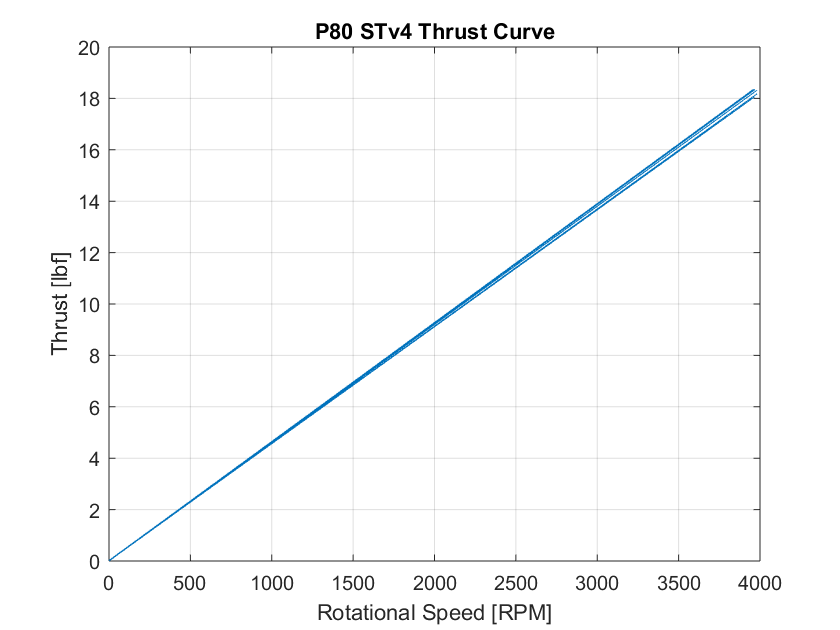

figure(1)
plot(rot_speed_rpm, T); title('P80 STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

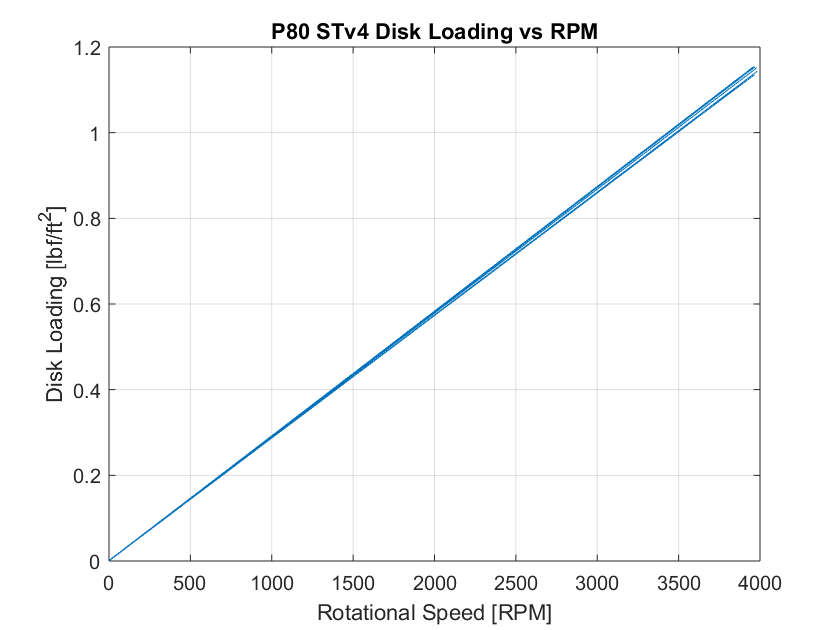


%{
figure(2)
plot(C_T, C_P,'o-');
title('P80 STv4 C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

figure(3)
plot(time, rot_speed_rpm); title('P80 STv4 Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('P80 STv4 Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off
%}

figure(5)
plot(rot_speed_rpm, disk_loading); title('P80 STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

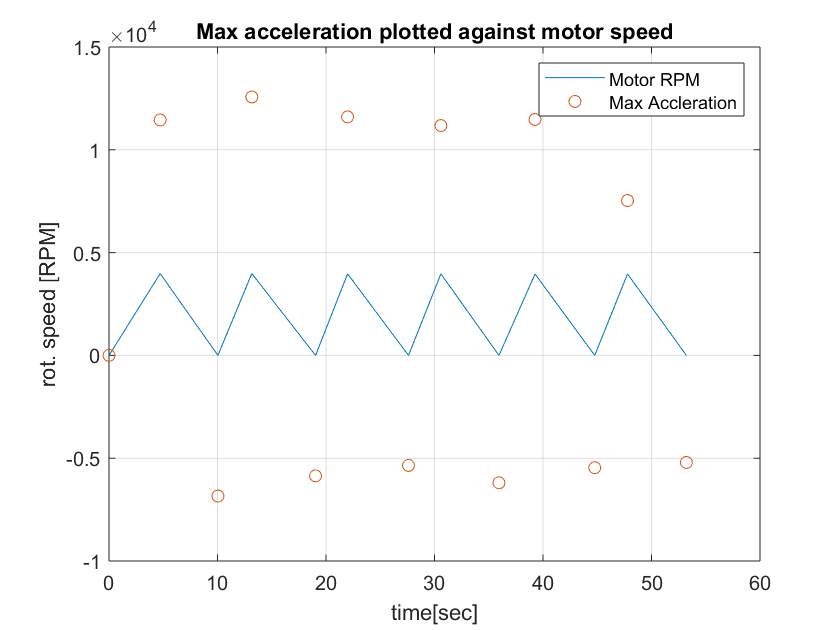

figure(6)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

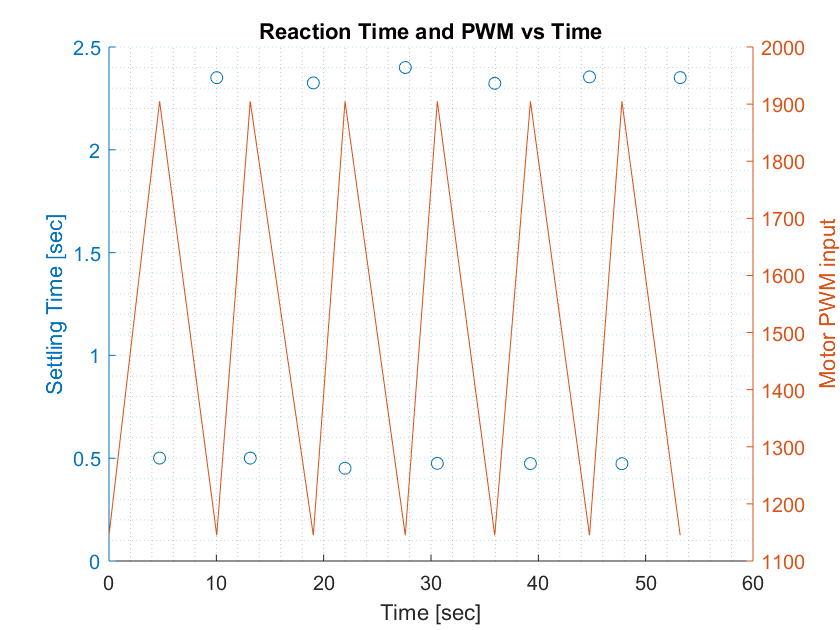


figure(7)
hold on
yyaxis left
plot(time,Settling_time, 'o');
ylabel('Settling Time [sec]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

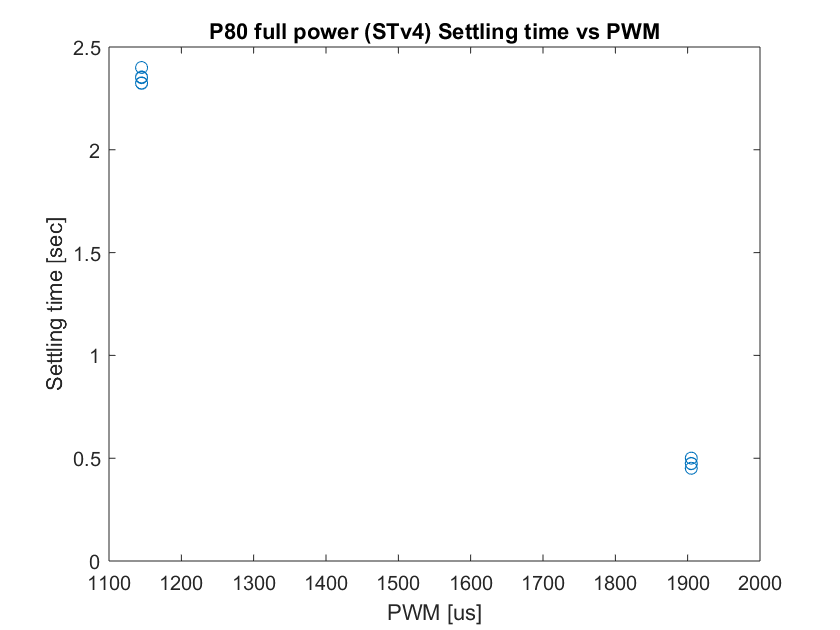


figure(8)
plot(PWM, Settling_time, 'o');
title('P80 full power (STv4) Settling time vs PWM');
xlabel('PWM [us]'); ylabel('Settling time [sec]');

## Comparing Data to Momentum Theory

%{
k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T, C_P, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data');
ylim([0 0.0003]); xlim([0 0.002]);

%}















